# Mapeo De Funciones

### 1) Se genera una matriz con los valores de la imagen original y la graficamos.

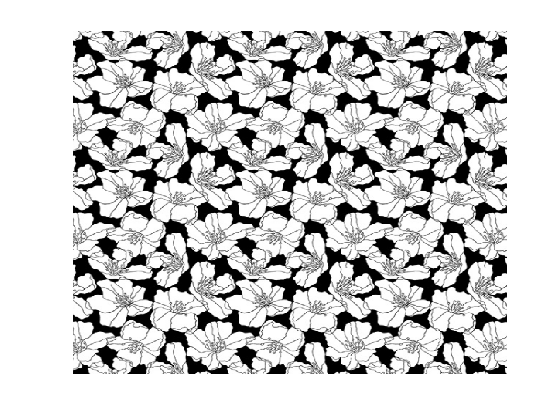

M2=imread('imagen2_pre.png');
figure
imagesc(M2)
axis off
colormap gray

### 2) Se genera una  maya compleja

Esta es la cual es afectada por la transformación.

[sm,sn] = size(M2);

[x,y] = meshgrid(linspace(-2*pi,2*pi,sm),linspace(-2*pi,2*pi,sn));
Z = x+y*1i;

### 3) Creamos la transformación y la aplicamos

Tambien se separa la parte real e imaginara para utilizarlos como coordenadas.

f = @(z) exp(z);
Zt = f(Z);

re = real(Zt);

re =     0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    0.0056
    0.0019    0.0019    0.0020    0.0020    0.0020    0.0021    0.0021    0.0022    0.0022    0.0023    0.0023    0.0024    0.0024    0.0025    0.0026    0.0026    0.0027    0.0027    0.0028    0.0029    0.0029    0.0030    0.0031    0.0031    0.0032    0.0033    0.0033    0.0034    0.0035    0.0036    0.0037    0.0037    0.0038    0.0039    0.0040    0.0041    0.0042    0.0043    0.0044    0.0045    0.0046    0.0047    0.0048    0.0049    0.0050    0.0051    0.0052    0.0054    0.0055    

im = imag(Zt);

im =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

### 4) Creación de vactores de coordenadas y de intensidad 

Las coordenadas salen de la malla ya transformada y la intensidad de la imágen original. 

x = reshape(re,1,[]);
y = reshape(im,1,[]);
int = reshape(M2,1,[]);

La imagen se crea utilizando los vectores, pues de forma ordenada se le entregan valores a las coordenadas.

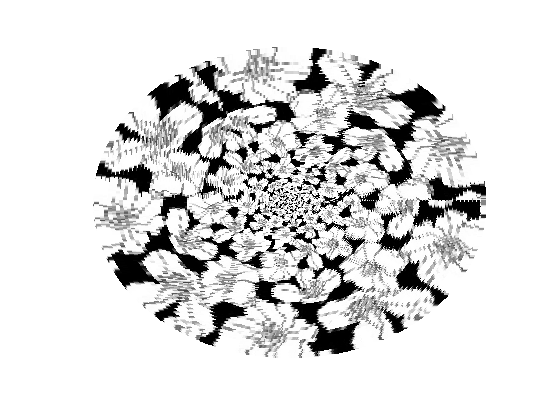

figure
scatter(x,y,20,int,'filled')
set(gca,'Color','g')
axis off
colormap gray